clear all;

%z1 = 0.2
%z2 = 0.8

%z1 = 0.5
%z2 = -0.8

%z1 = 0.1
%z2 = -0.3

%z1 = 0.2i
%z2 = -0.2i

z1 = -0.3 + 0.7i

z1 = -0.3000 + 0.7000i

z2 = -0.3 - 0.7i

z2 = -0.3000 - 0.7000i


rh = 2;
rb = 1;

p = z1 + z2

p = -0.6000

q = z1 * z2

q = 0.5800


l1 = p - rh;
l2 = q - 1;

R = [-0.02, -0.2; 0.02, -0.2];
L = [l1; l2];
K = pinv(R) * L;
disp(K);

   54.5000
    7.5500



k1 = K(1,1)

k1 = 54.5000

k2 = K(2,1)

k2 = 7.5500

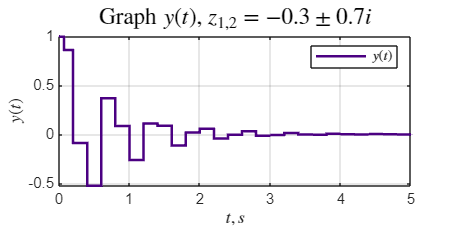



open_system('schem_2');
set_param('schem_2/y', 'VariableName', 'y');

out = sim('schem_2');


y_data = out.y.Data;
t_time = out.y.Time;


% Определяем цвета для линий
a_color = '#4B0082'; 
b_color = '#7B68EE';
c_color = '#800080'; 
d_color = '#0000CD';
e_color = '#EE82EE';

figure('Position', [100 100 800 400]);
stairs(t_time, y_data, '-', 'LineWidth', 1.5, 'Color', a_color);
hold on;
%plot(t_time, x_M_data(:,1), '--', 'LineWidth', 1.5, 'Color', d_color);
%plot(t_time, x_data(:,2), '-', 'LineWidth', 1.5, 'Color', e_color);
%plot(t_time, x_M_data(:,2), '--', 'LineWidth', 1.5, 'Color', c_color);

grid on;
%title('Graph $y(t)$, $z_{1,2} = \pm 0.2i $', 'Interpreter', 'latex', 'FontSize', 14);
title('Graph $y(t)$, $z_{1,2} = -0.3 \pm 0.7i $', 'Interpreter', 'latex', 'FontSize', 14);

%title(sprintf('Graph $y(t)$, $z_1 = %.1f$, $z_2 = %.1f$', z1, z2), 'Interpreter', 'latex', 'FontSize', 14);
ylabel('$y(t)$','Interpreter', 'latex' );
xlabel('$t, s$', 'Interpreter', 'latex');
legend('$y(t)$','Interpreter', 'latex')
xlim([0 5])
hold off;

full_path = ['C:\Users\user\Desktop\STUDY_2.0\4 курс робототехника\ДискрСистУпр\DiscreteSystems\lab_1\Discrete_report_1\pic\' ...
    '2_y_5.png'];

exportgraphics(gcf, full_path, 'Resolution', 300);